## BFGS

### Optimización 24O

#### Alan Badillo Salas

`Diciembre 17, 2024`

# Descenso de Gradiente con búsqueda lineal para $\alpha_k$

### Paso 1

Definimos la función $f$


$$f(x) = 3(x_1 - 1)^2 + 2.9x_1x_2 + 2(x_2 - 1)^2$$


Graficamos las curvas de nivel

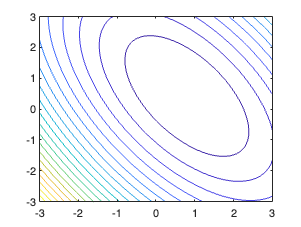

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);

F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

### Paso 2

Inicializamos un vector inicial $x_0$


$$x_0 = (3, 3)$$


Calculamos la dirección de descenso $d$


$$d = -\nabla f(x)$$


x0 = [3, 3]

x0 =      3     3



d = -df(x0)

d =   -20.7000  -16.7000


Graficamos el gradiente

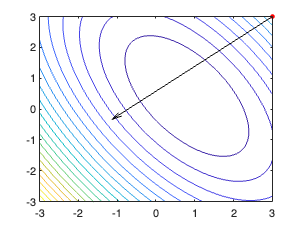

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

% x0
plot(x0(1), x0(2), "r*", ...
    MarkerSize = 4, LineWidth = 2);

% d
quiver(x0(1), x0(2), d(1), d(2), 0.2, "k");

Iteramos las direcciones de descenso calculando $x_{k+1}$

xk = x0

xk =      3     3


dk = d

dk =   -20.7000  -16.7000


x_list = xk;
d_list = dk;
a_list = [1, 0];
for i = 1:5
    a = line_search("f", "df", xk, dk)
    xk = xk + a * dk;
    dk = -df(xk)
    x_list(i + 1, :) = xk;
    d_list(i + 1, :) = dk;
    a_list(i + 1, :) = [a, 0];
end

[0] ~1 (1.000000 | 0.0000, Inf) 
[1] ~1 (0.500000 | 0.0000, 1.0000) 
[2] ~1 (0.250000 | 0.0000, 0.5000) 
[3] OK (0.125000 | 0.0000, 0.2500) 


a = 0.1250

dk =     0.8788   -0.8462


[0] ~1 (1.000000 | 0.0000, Inf) 
[1] ~2 (0.500000 | 0.0000, 1.0000) 
[2] ~2 (0.750000 | 0.5000, 1.0000) 
[3] ~2 (0.875000 | 0.7500, 1.0000) 
[4] ~1 (0.937500 | 0.8750, 1.0000) 
[5] ~2 (0.906250 | 0.8750, 0.9375) 
[6] ~2 (0.921875 | 0.9062, 0.9375) 
[7] ~2 (0.929688 | 0.9219, 0.9375) 
[8] ~2 (0.933594 | 0.9297, 0.9375) 
[9] ~1 (0.935547 | 0.9336, 0.9375) 


a = 0.9346

dk =    -1.7552   -0.0644


[0] ~1 (1.000000 | 0.0000, Inf) 
[1] ~1 (0.500000 | 0.0000, 1.0000) 
[2] OK (0.250000 | 0.0000, 0.5000) 


a = 0.2500

dk =     0.9243    1.2725


[0] ~1 (1.000000 | 0.0000, Inf) 
[1] ~1 (0.500000 | 0.0000, 1.0000) 
[2] OK (0.250000 | 0.0000, 0.5000) 


a = 0.2500

dk =    -1.3847   -0.6701


[0] ~1 (1.000000 | 0.0000, Inf) 
[1] ~1 (0.500000 | 0.0000, 1.0000) 
[2] OK (0.250000 | 0.0000, 0.5000) 


a = 0.2500

dk =     1.1782    1.0039



x_list

x_list =     3.0000    3.0000
    0.4125    0.9125
    1.2338    0.1216
    0.7949    0.1055
    1.0260    0.4237
    0.6798    0.2561


d_list

d_list =   -20.7000  -16.7000
    0.8788   -0.8462
   -1.7552   -0.0644
    0.9243    1.2725
   -1.3847   -0.6701
    1.1782    1.0039


a_list

a_list =     1.0000         0
    0.1250         0
    0.9346         0
    0.2500         0
    0.2500         0
    0.2500         0


Graficamos la lista de puntos obtenidos

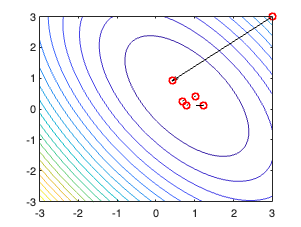

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

for k = 1:size(x_list, 1)
    % Puntos x_k
    plot(x_list(k, 1), x_list(k, 2), "ro", "MarkerSize", 6, "LineWidth", 1.5);

    % Gradientes g_k (escala ajustada para visualización)
    quiver(x_list(k, 1), x_list(k, 2), d_list(k, 1), d_list(k, 2), a_list(k, 1) * 0.125, "k");
end

# BFGS

### Paso 1

Definimos la función $f$


$$f(x) = 3(x_1 - 1)^2 + 2.9x_1x_2 + 2(x_2 - 1)^2$$


Graficamos las curvas de nivel

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);

F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

### Paso 2

Inicializamos un vector inicial $x_0$


$$x_0 = (3, 3)$$


x0 = [3, 3]

x0 =      3     3


Aplicamos BFGS para encontrar $x^* = x_{k}$

[xk, mlist] = bfgs("f", "df", x0, eye(2), 10e-7);

     2




xk

xk =     0.7430    0.4945


Graficamos el gradiente

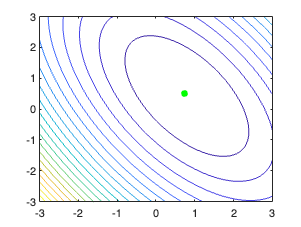

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

% Solución óptima xk
plot(xk(1), xk(2), "g*", ...
    MarkerSize = 6, LineWidth = 2);


% d
% quiver(x0(1), x0(2), d(1), d(2), 0.2, "k");

Graficamos los puntos iterados

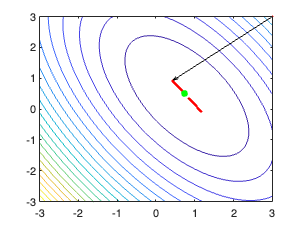

x = linspace(-3, 3, 100);
y = linspace(-3, 3, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

for k = 1:size(mlist, 1)
%for k = 1:100
    p_xk = mlist(k, :, 3);

    % Puntos x_k
    plot(p_xk(1), p_xk(2), "ro", "MarkerSize", 1, "LineWidth", 1);

    p_dk = mlist(k, :, 1);

    % Gradientes g_k (escala ajustada para visualización)
    quiver(p_xk(1), p_xk(2), p_dk(1), p_dk(2), 0.125, "k");
end

% Solución óptima xk
plot(xk(1), xk(2), "g*", ...
    MarkerSize = 6, LineWidth = 2);

# Caso de estudio 1

### Paso 1

Definimos la función $f$


$$f(x) = 100\left(x_2 - x_1^2\right)^2 + (1-x_1)^2$$


Graficamos las curvas de nivel

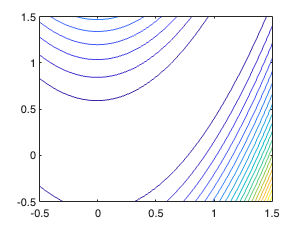

x = linspace(-0.5, 1.5, 100);
y = linspace(-0.5, 1.5, 100);

[X, Y] = meshgrid(x, y);

F = arrayfun(@(x, y) f1([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

### Paso 2

Inicializamos un vector inicial $x_0$


$$x_0 = (1.2, 1.2)$$


x0 = [1.2, 1.2]

x0 =     1.2000    1.2000


Aplicamos BFGS para encontrar $x^* = x_{k}$

[xk, mlist] = bfgs("f1", "df1", x0, eye(2), 10e-4);

     2




xk

xk =     0.6509    0.5552


Graficamos el gradiente

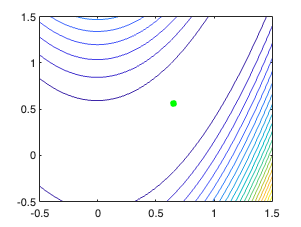

x = linspace(-0.5, 1.5, 100);
y = linspace(-0.5, 1.5, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f1([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

% Solución óptima xk
plot(xk(1), xk(2), "g*", ...
    MarkerSize = 6, LineWidth = 2);


% d
% quiver(x0(1), x0(2), d(1), d(2), 0.2, "k");

Graficamos los puntos iterados

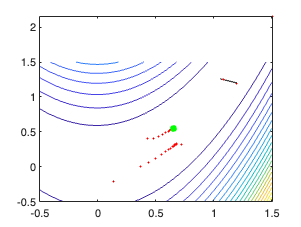

x = linspace(-0.5, 1.5, 100);
y = linspace(-0.5, 1.5, 100);

[X, Y] = meshgrid(x, y);


F = arrayfun(@(x, y) f1([x, y]), X, Y);

figure;
contour(X, Y, F, 20);
hold on;

for k = 1:size(mlist, 1)
%for k = 1:100
    p_xk = mlist(k, :, 3);

    % Puntos x_k
    plot(p_xk(1), p_xk(2), "ro", "MarkerSize", 1, "LineWidth", 1);

    p_dk = mlist(k, :, 1);

    % Gradientes g_k (escala ajustada para visualización)
    quiver(p_xk(1), p_xk(2), p_dk(1), p_dk(2), 0.00125, "k");
end

% Solución óptima xk
plot(xk(1), xk(2), "g*", ...
    MarkerSize = 6, LineWidth = 2);